# **繪圖軟體應用 第3周(9/25)**

clear;clc
v1=[6 7 8 9]

v1 =      6     7     8     9


v1([2,4])

ans =      7     9


v1([2 4])

ans =      7     9


v1(:)

ans =      6
     7
     8
     9


v1(6) = 3  % 擴展元素數目

v1 =      6     7     8     9     0     3


v1(end)

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

ans = -17

v1(3:5)=1

v1 =      6     7     1     1     1     3


v1(1:2:end)

ans =      6     1     1


v1(end:-1:1)

ans =      3     1     1     1     7     6


M=[1 5 6 7; 1 5 6 7; 2 3 7 8];
M=[M,[44;77;88]]

M =      1     5     6     7    44
     1     5     6     7    77
     2     3     7     8    88


M=[[8 9 10 11 12];M]

M =      8     9    10    11    12
     1     5     6     7    44
     1     5     6     7    77
     2     3     7     8    88


M(4:-1:1,:)

ans =      2     3     7     8    88
     1     5     6     7    77
     1     5     6     7    44
     8     9    10    11    12


**索引值結構**

M([5;7;9])

ans =      9
     5
    10


M([1 3],[4 5])

ans =     11    12
     7    77


**索引值轉換**

ind = sub2ind([3,4],2,3)  %第幾個元素

ind = 8

[row,col]=ind2sub([3,4],8)

row = 2

col = 3

[row2,col2]=ind2sub([3,4],[8 4 12])

row2 =      2     1     3


col2 =      3     2     4


## 三維陣列

A(:,:,1)=[7 8 9;10 11 12];
A(:,:,2)=[13 14 15; 16 17 18];
A

A = A(:,:,1) =

     7     8     9
    10    11    12


A(:,:,2) =

    13    14    15
    16    17    18


## 陣列建立函數

c = eye(3)

c =      1     0     0
     0     1     0
     0     0     1


diag([1 2 3 4])

ans =      1     0     0     0
     0     2     0     0
     0     0     3     0
     0     0     0     4


**亂數陣列**

用途 :

- 工業界濾波器，先知道一個函數，再產生雜訊合成，想辦法把雜訊濾掉

- 樂透電腦選號

randi(5,5) %1到5的5*5亂數矩陣

ans =      5     1     1     4     1
     1     3     5     3     2
     2     4     2     1     2
     2     2     5     4     1
     1     4     5     3     1


randi(5,[3,2])

ans =      5     3
     2     3
     5     2


randi([1,10],[3,2])

ans =      1     3
    10     3
     1     6


rand()  %0到1之間均勻分布的亂數

ans = 0.8016

rand(3)

ans =     0.5224    0.3576    0.1230
    0.7052    0.9211    0.2841
    0.8615    0.4339    0.7621


rand(3,4)

ans =     0.5572    0.2737    0.4120    0.8692
    0.9170    0.6175    0.0631    0.7032
    0.9219    0.6799    0.8961    0.3547


randn() %平均值為0，標準差為1的常態分佈亂數

ans = 0.1795

randn(3) %平均值為0，標準差為1的常態分佈亂數

ans =    -1.1849   -1.8861    0.0942
    1.0607   -1.7566    1.0617
    0.5829   -0.9368   -1.6830


randn(3,4) %平均值為0，標準差為1的常態分佈亂數

ans =    -1.5308    0.0065    1.7878   -0.1861
    0.3491    0.5926   -0.7948    0.9384
   -0.0038   -0.5454    0.3750    1.3872


seed = 999

seed = 999

rng(seed) %設定亂數種子為seed

測試

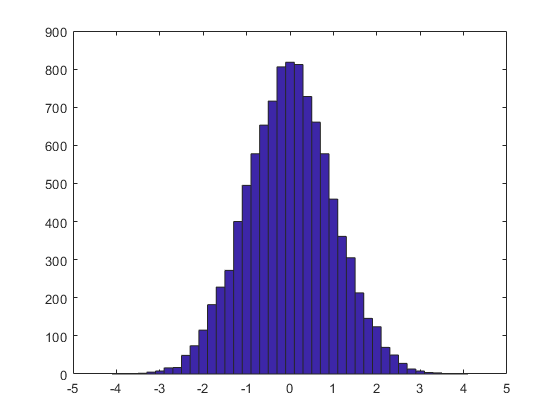

B=randn(1,10000);         %常態分布
hist(B,-4:0.2:4)

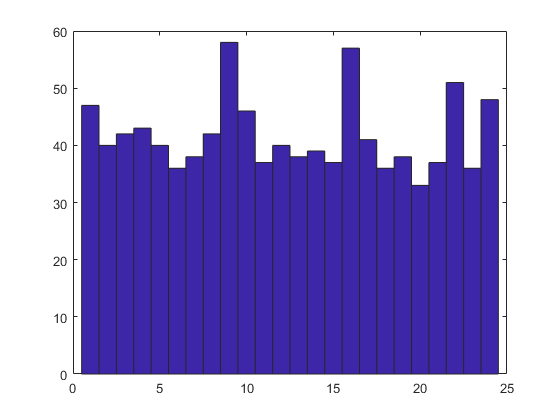

C=randi([1,24],[1,1000]); %非常態分佈
hist(C,1:24)

## 陣列元素提取

diag(M)'

ans =      8     5     6     8


diag(M,1)'   %第1個對角線

ans =      9     6     7    88


diag(M,-1)'  %第-1個對角線

ans =      1     5     7


triu(M)

ans =      8     9    10    11    12
     0     5     6     7    44
     0     0     6     7    77
     0     0     0     8    88


triu(M,2)

ans =      0     0    10    11    12
     0     0     0     7    44
     0     0     0     0    77
     0     0     0     0     0


tril(M)

ans =      8     0     0     0     0
     1     5     0     0     0
     1     5     6     0     0
     2     3     7     8     0


tril(M,-2)

ans =      0     0     0     0     0
     0     0     0     0     0
     1     0     0     0     0
     2     3     0     0     0


## **陣列元素重排**

a=rand(3,4)

a =     0.9753    0.3761    0.4343    0.6566
    0.1398    0.0492    0.6698    0.0853
    0.2650    0.1418    0.3268    0.9463


h = reshape(a,6,2)

h =     0.9753    0.4343
    0.1398    0.6698
    0.2650    0.3268
    0.3761    0.6566
    0.0492    0.0853
    0.1418    0.9463


h1 = reshape(a,[6,2])

h1 =     0.9753    0.4343
    0.1398    0.6698
    0.2650    0.3268
    0.3761    0.6566
    0.0492    0.0853
    0.1418    0.9463


M

M =      8     9    10    11    12
     1     5     6     7    44
     1     5     6     7    77
     2     3     7     8    88


rot90(M)

ans =     12    44    77    88
    11     7     7     8
    10     6     6     7
     9     5     5     3
     8     1     1     2


d = magic(4)

d =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


flipdim(d,2)  %flipdim(d,n)  以第n維度為中心翻轉

ans =     13     3     2    16
     8    10    11     5
    12     6     7     9
     1    15    14     4


驚訝的結果(還好啦)

a=[1 2; 4 5]

a =      1     2
     4     5


b = [4 5; 3 8]

b =      4     5
     3     8


a+b

ans =      5     7
     7    13


a-b

ans =     -3    -3
     1    -3


a*b

ans =     10    21
    31    60


a.*b

ans =      4    10
    12    40


expm(a) %矩陣的指數

ans =   136.1004  185.0578
  370.1155  506.2159
